a)iii) Investigate best fits to the origin-destination demand data in the form cOiDj/dα ij, where dij is the distance data computed in (a)(ii), and c and α are constants to be fitted. You may use a combination of graphical and analytical techniques and full marks will be reserved for scripts which explain methods, discuss results and provide other insightful comment.

In order to fit $\alpha$ and c it was neccessary to convert the gravity equation to log scale and rearrange it into the familar $y=mx+c$ form, as shown in the equations below. It was then possible to use the MATLAB function `'fitlm'`. The leading diagonal of the OD matrix was excluded because ....


$$$T_{ij} = \frac{cO_i D_j}{d^\alpha} $
$$



$$log(T_{ij}) = log(c) + log(O_iD_j) - \alpha log(d)$$



$$log\Big(\frac{T_{ij}}{O_iD_j}\Big) =  \alpha log(d) +  log(c)$$



$$y = mx +c$$


C: 0.000303
Alpha: 0.755779


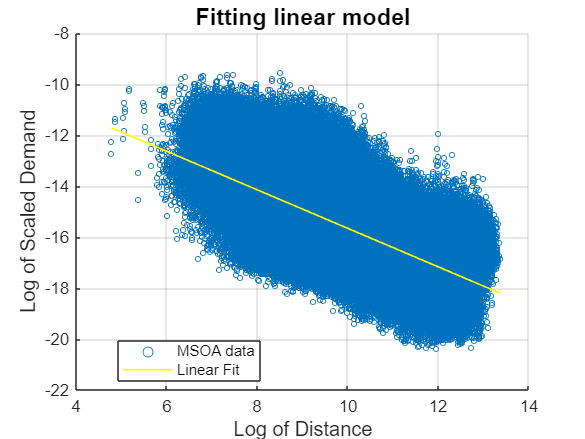

[i, j, Fij] = find(MSOAdata.odMatrix);
% Exclude flows where origin and destination are the same
valid_indices = i ~= j;
i = i(valid_indices);
j = j(valid_indices);
Fij = Fij(valid_indices);

% Get total flows for each origin-destination pair
O_i = MSOAdata.originSums(i);
D_j = MSOAdata.destinationSums(j);
% Compute the linear indices for the distance matrix
linear_indices = sub2ind(size(MSOAdata.distanceMatrix), i, j);
% Extract distances for each pair
d_ij = MSOAdata.distanceMatrix(linear_indices);


% Compute the dependent variable y = ln(Fij / (O_i * D_j))
y = log(Fij ./ (O_i .* D_j));
% Compute the independent variable x = ln(d_ij)
x = log(d_ij);
mdl = fitlm(x, y); % Perform linear regression

% Extract c and alpha
c = exp(mdl.Coefficients.Estimate(1));
alpha = -mdl.Coefficients.Estimate(2);

plotting1(mdl,x,y,c,alpha);

For interest, I created unconstrained gravity models for other values of $\alpha$ and c and calculated the root mean square error (RMSE) of the model compared to the observed data. This is shown in the table below, which demonstrates that the values from the linear fit resulted in the most accurate model. When calculated the RMSE I noticed that the leading diagonal of the gravity model was all `'Inf'` and so this was excluded when finding the RMSE, for simplicity. The table also shows that the basic values for $\alpha$ and c of 2 and 1, respectively, also result in a decent model. 

c_values = [0.0001, 0.000303, 0.0005, 1];
alpha_values = [0.5, 0.755779, 1, 2];
for c = c_values
    for alpha = alpha_values
        makegravity(MSOAdata, c, alpha);
    end
end

Table 1: Root Mean Square Error (RMSE) for varied values of $\alpha$ and c

Finally, a log-scale scatter plot and the residuals were plotted. From plotting the residuals, it is clear to see that the model makes many more underpredictions rather than overpredictions. This is further discussed in question 1c.

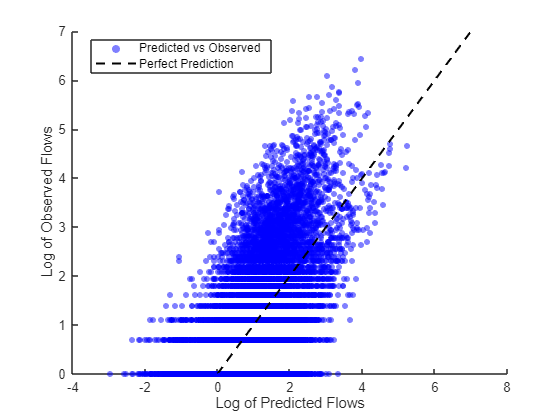

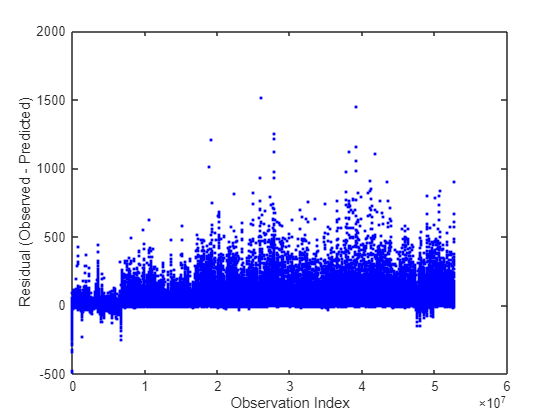

% plot log-scatter and residuals for alpha and c
MSOAdata = makegravity(MSOAdata, c, alpha);
plotting2(MSOAdata)